# IIR Filters

## 4.1. Realising IIR filters 

load("ECG_with_noise.mat");
fs = 500;
time = (0:length(nECG)-1)/fs; %time_array
nfft = 1024;
window = rectwin(length(nECG));

% Creating a lowpass butterworth filter

lowpass_wc = 0.32;
lowpass_M = 30; % Since unstable at very high orders
[low_butter_b,low_butter_a] = butter(lowpass_M, lowpass_wc,'low');

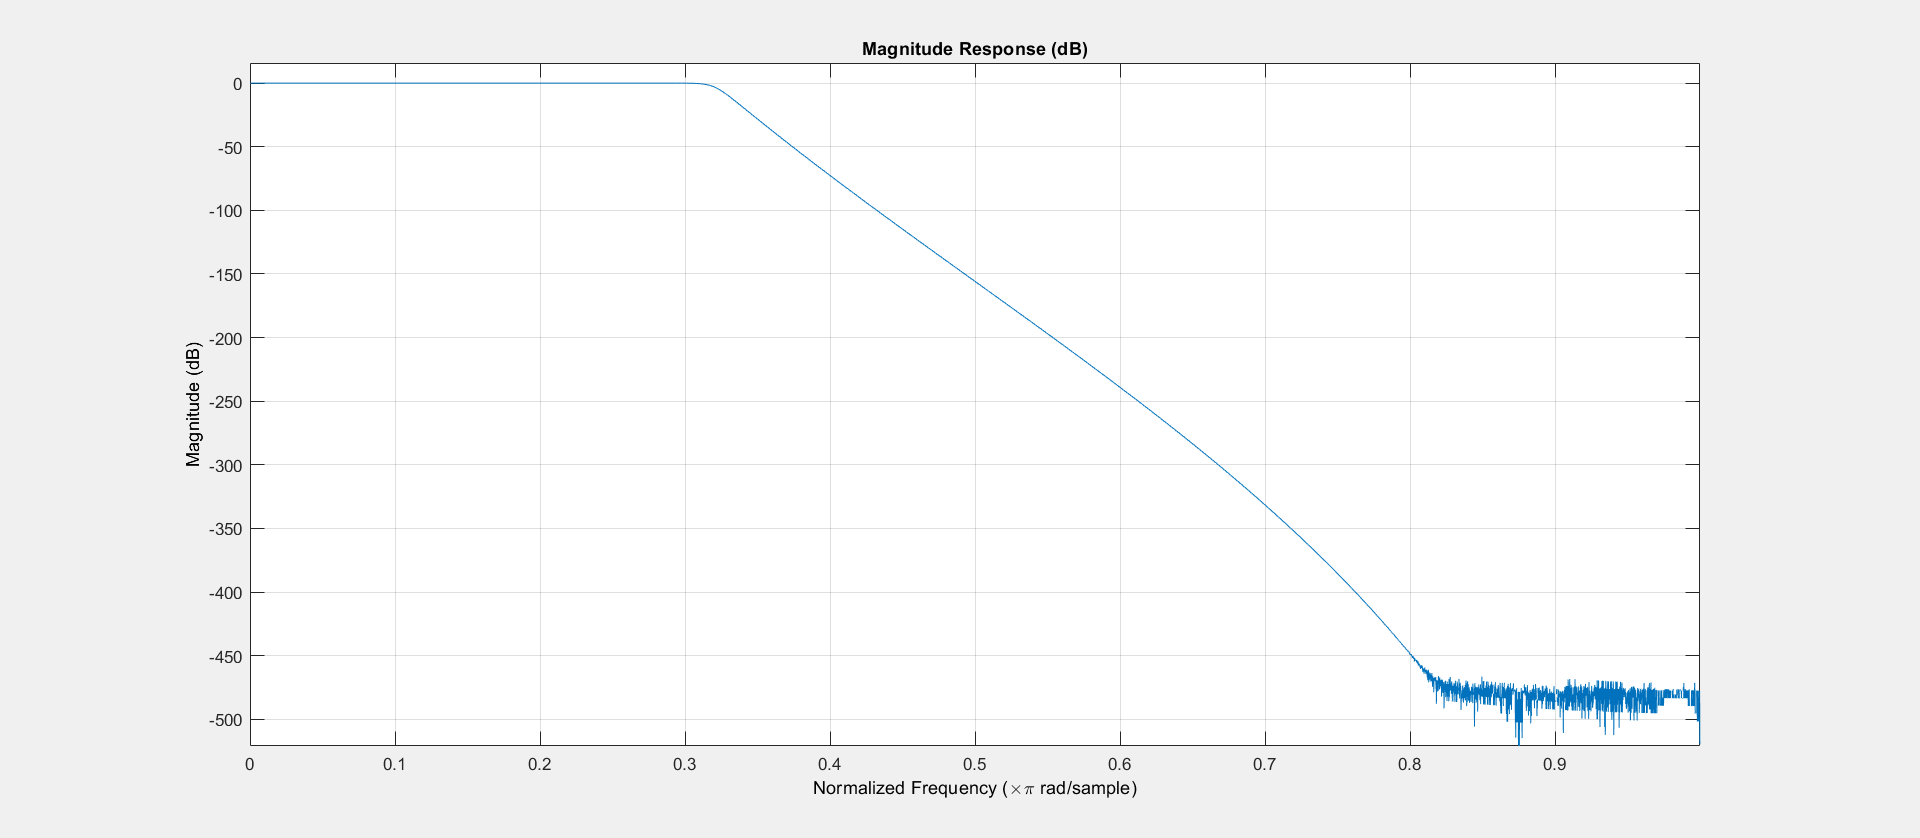

fvtool(low_butter_b,low_butter_a);

% Creating a highpass butterworth filter

highpass_wc = 0.04;
highpass_M = 10;
[high_butter_b,high_butter_a] = butter(highpass_M, highpass_wc,'high');

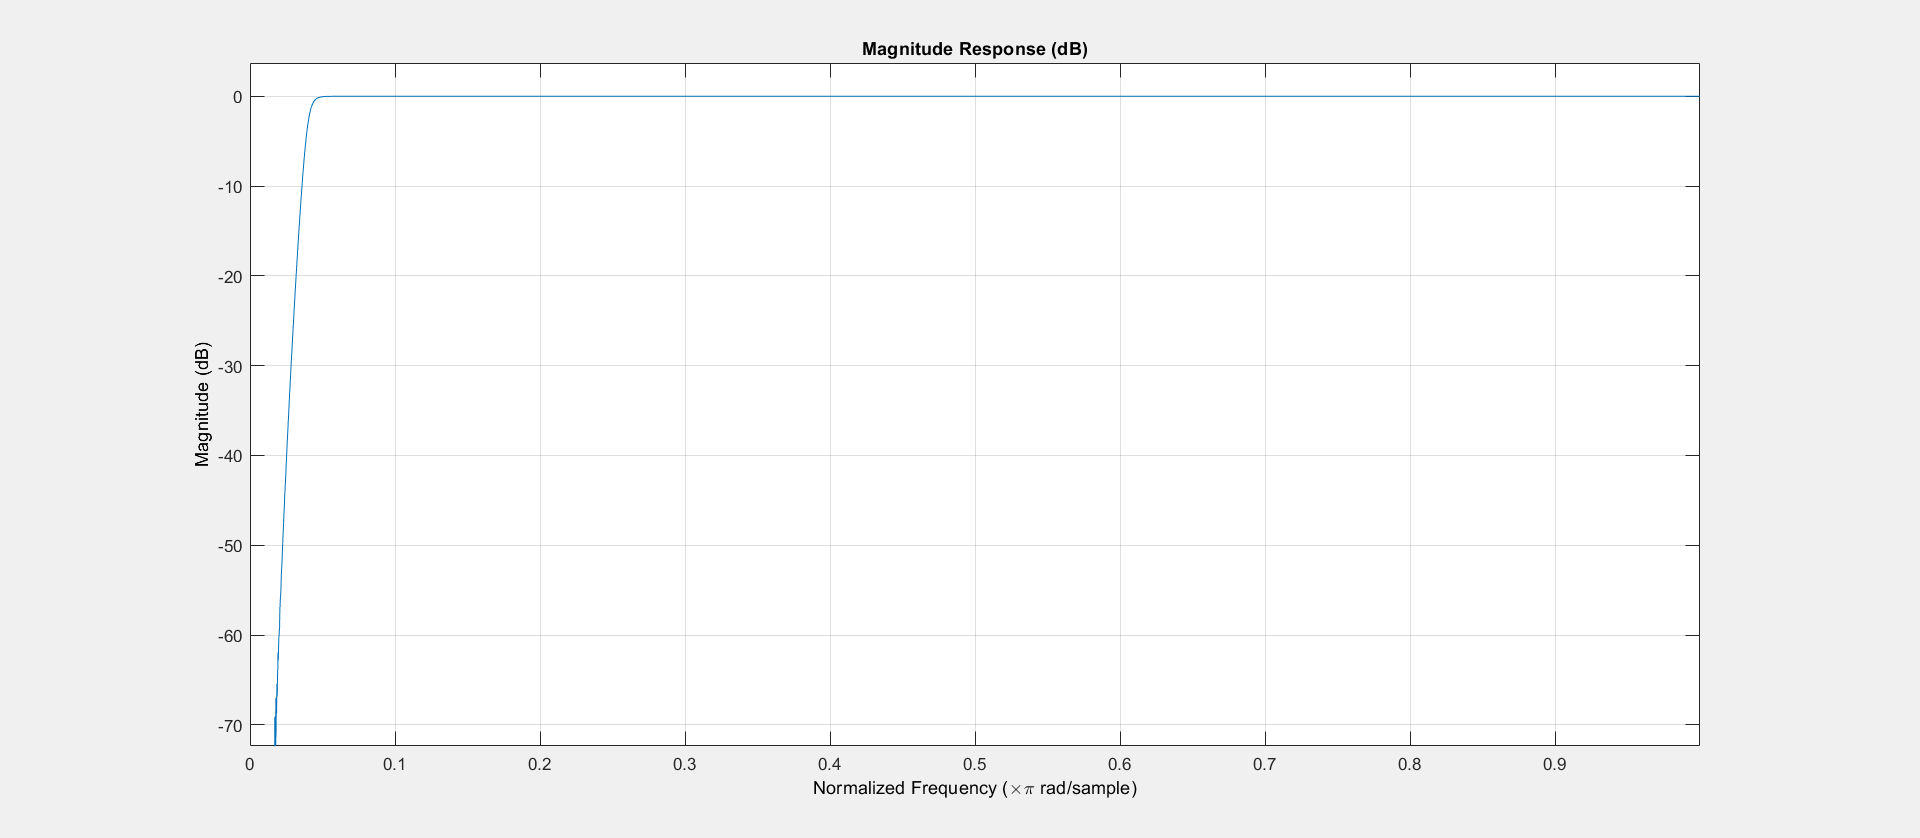

fvtool(high_butter_b,high_butter_a);

fs = 500; 
notch_wc = 50;  
q = 35; 
bw = (notch_wc/(fs/2))/q;
[comb_iir_b,comb_iir_a] = iircomb(fs/notch_wc, bw, 'notch'); % Note type flag 'notch'

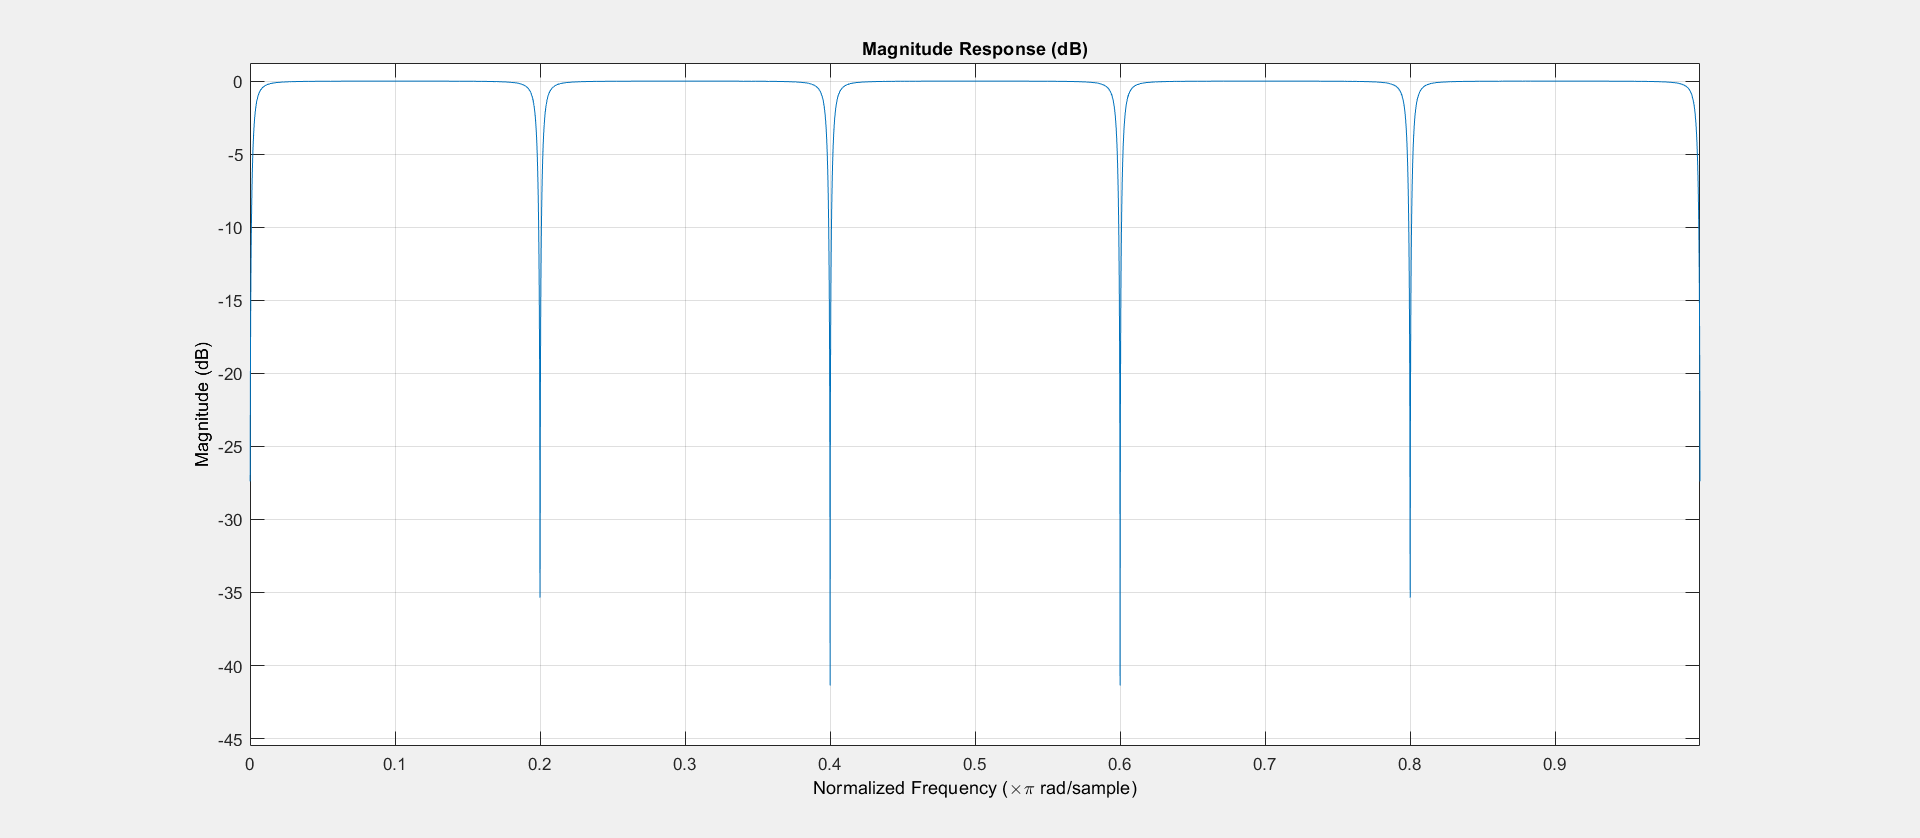

fvtool(comb_iir_b,comb_iir_a);

% Create digital filter objects
highpass_iir_filt_object = dfilt.df2(high_butter_b, high_butter_a);  % Filter 1
lowpass_iir_filt_object = dfilt.df2(low_butter_b, low_butter_a);  % Filter 2
comb_iir_filt_object = dfilt.df2(comb_iir_b, comb_iir_a);  % Filter 3

cascade_filter_iir = dfilt.cascade(comb_iir_filt_object, lowpass_iir_filt_object, highpass_iir_filt_object);

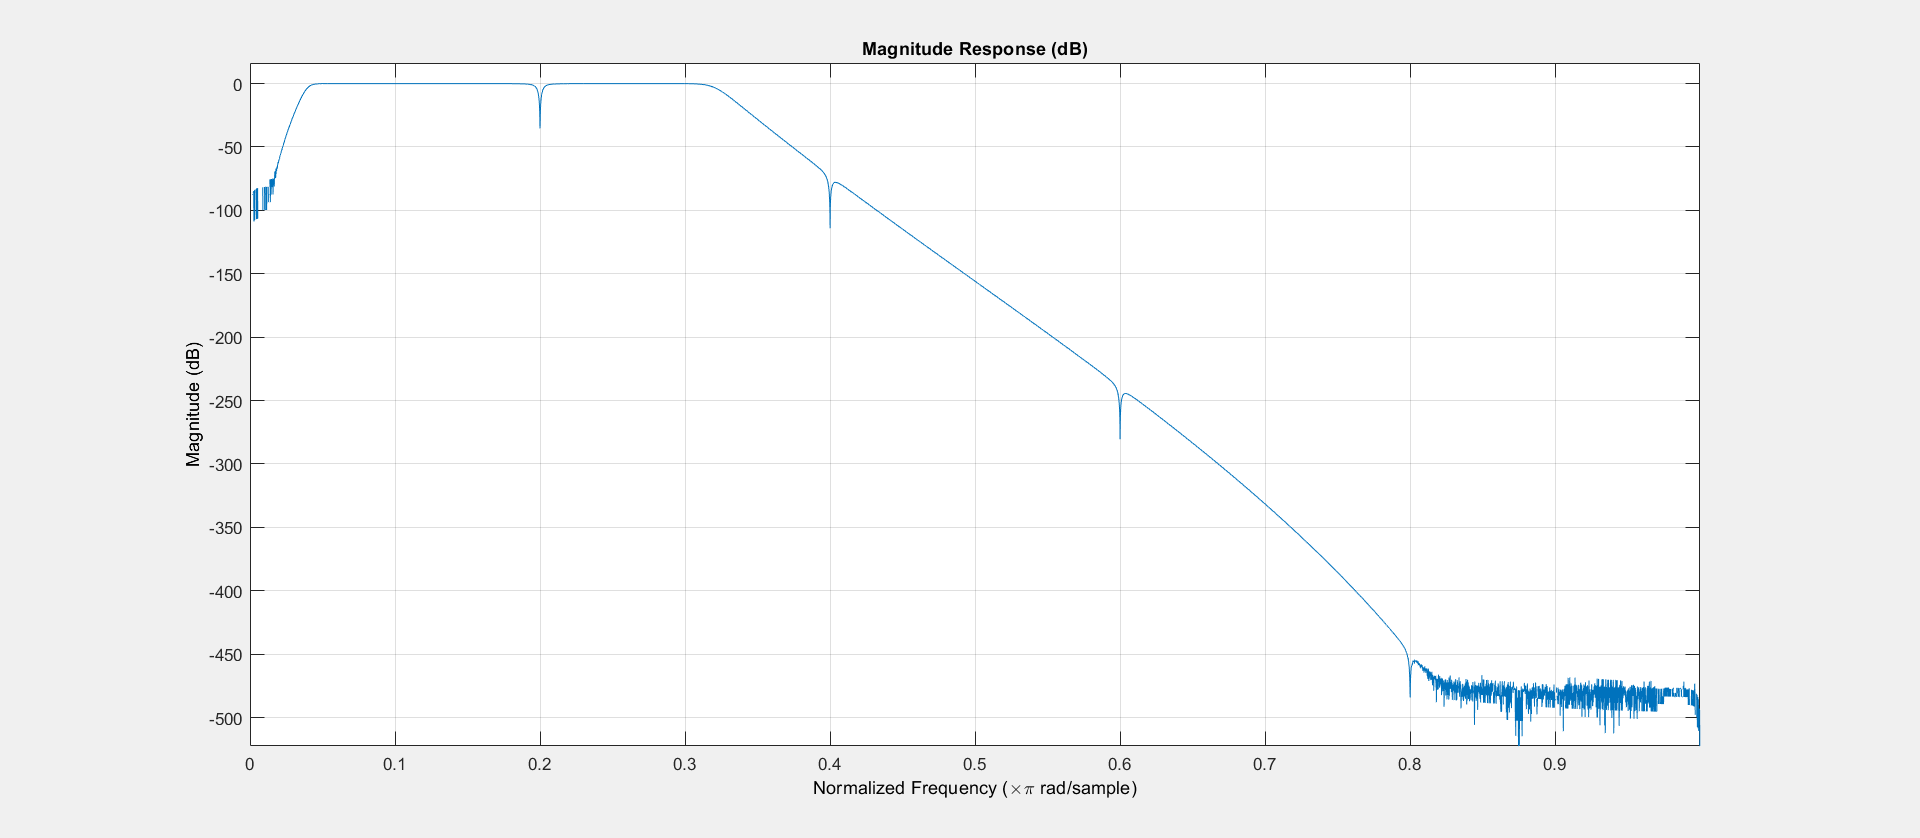

fvtool(cascade_filter_iir);

## 4.2. Filtering methods using IIR filters 

% Filter signal using cascaded IIR

cascaded_filtered_ECG_ = filter(cascade_filter_iir, nECG);
cascaded_filtered_ECG_iir = [cascaded_filtered_ECG_(591:end),zeros(1,590)];

% Filter signal using the created butterworth filters

highpass_iir_filtered_signal = filter(high_butter_b,high_butter_a,nECG);
lowpass_iir_filtered_signal = filter(low_butter_b,low_butter_a,nECG);
com_iir_filtered_signal = filter(comb_iir_b,comb_iir_a,nECG);

% Filter signals using the forward backward filtering

highpass_iir_filtered_signal_fb = filtfilt(high_butter_b,high_butter_a,nECG);
lowpass_iir_filtered_signal_fb = filtfilt(low_butter_b,low_butter_a,nECG);
com_iir_filtered_signal_fb = filtfilt(comb_iir_b,comb_iir_a,nECG);


% cascaded filter with forward and backward pass

com_iir_filtered_signal_fb_cascaded = filtfilt(comb_iir_b,comb_iir_a,nECG);
lowpass_iir_filtered_signal_fb_cascaded = filtfilt(low_butter_b,low_butter_a,com_iir_filtered_signal_fb);
highpass_iir_filtered_signal_fb_cascaded = filtfilt(high_butter_b,high_butter_a,lowpass_iir_filtered_signal_fb);

cascaded_filtered_ECG_iir_fb = highpass_iir_filtered_signal_fb_cascaded;


load('cascaded_filtered_ECG_fir.mat')

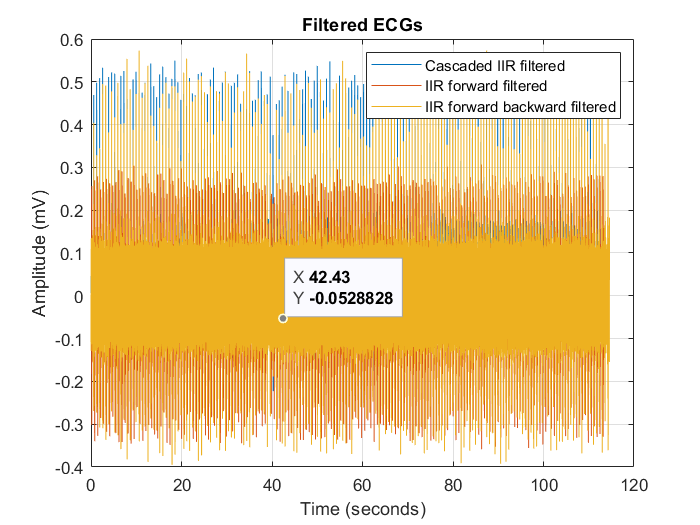

figure;
plot(time, cascaded_filtered_ECG_fir);
hold on;

plot(time, cascaded_filtered_ECG_iir);
hold on; 

plot(time, cascaded_filtered_ECG_iir_fb);

legend('Cascaded IIR filtered', 'IIR forward filtered', 'IIR forward backward filtered');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Filtered ECGs')
grid on;

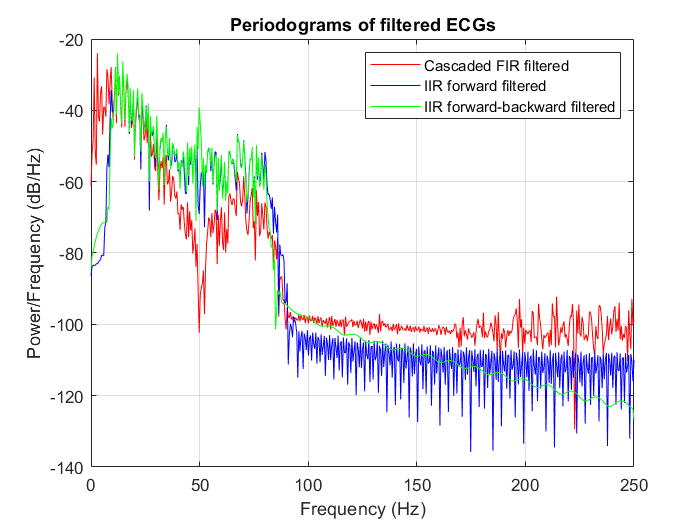

% Plotting PSDs of filtered signals

[pxx1, f1] = periodogram(cascaded_filtered_ECG_fir, window, nfft, fs);
[pxx2, f2] = periodogram(cascaded_filtered_ECG_iir, window, nfft, fs);
[pxx3, f3] = periodogram(cascaded_filtered_ECG_iir_fb, window, nfft, fs);

figure;
plot(f1, 10*log10(pxx1), 'r');  % Plot periodogram in red
hold on;
plot(f2, 10*log10(pxx2), 'b');  % Plot periodogram in blue
hold on;
plot(f3, 10*log10(pxx3), 'g');  % Plot periodogram in green

legend('Cascaded FIR filtered', 'IIR forward filtered', 'IIR forward-backward filtered');
title('Periodograms of filtered ECGs');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;
hold off;